## Step 1 - Load Model

gimbalsModel = 'Gimbals.stl'; % Required Input

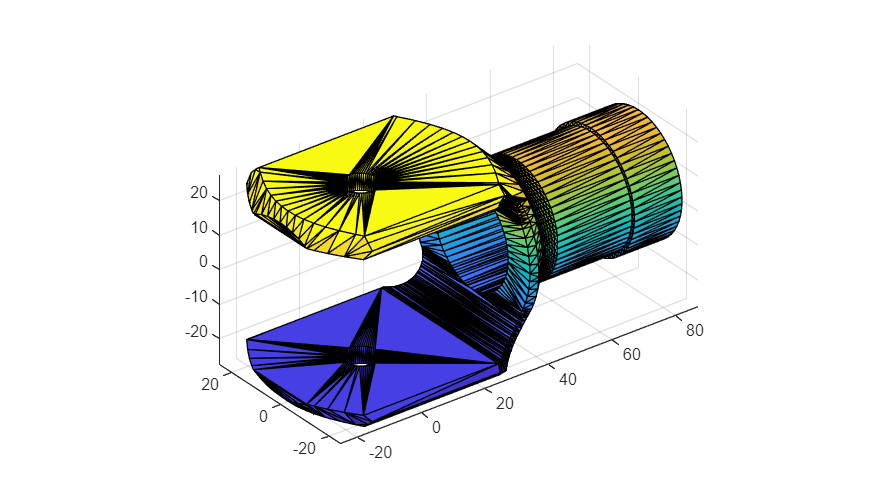


figure('Units','normalized', 'Position',[0 0 0.4 0.4])
trisurf(stlread(gimbalsModel));
axis equal

### Material Properties

E= 210e9; %[Pa] - Required Input
nu = 0.3; % Required Input
rho = 7.8e-6; %[kg/m^3] - Required Input

## Step 2 - Intefaces Locations

origins = [  0    0   25; ... % Required Input   
               80     0    0 ;... % Required Input        
              0    0   -25 ]; % Required Input
numFrames = size(origins,1);

## Step 3 - FE Mesh

feModel = createpde('structural','modal-solid');
importGeometry(feModel,gimbalsModel);
structuralProperties(feModel, ...
    'YoungsModulus',E, ...
    'PoissonsRatio',nu, ...
    'MassDensity',rho);
generateMesh(feModel, ...
    'GeometricOrder','quadratic', ...
    'Hmax',15, ... % Required Input
    'Hmin',5); % Required Input

## Step 4 - Set up the Multipoint Constraints for the Interface Frames

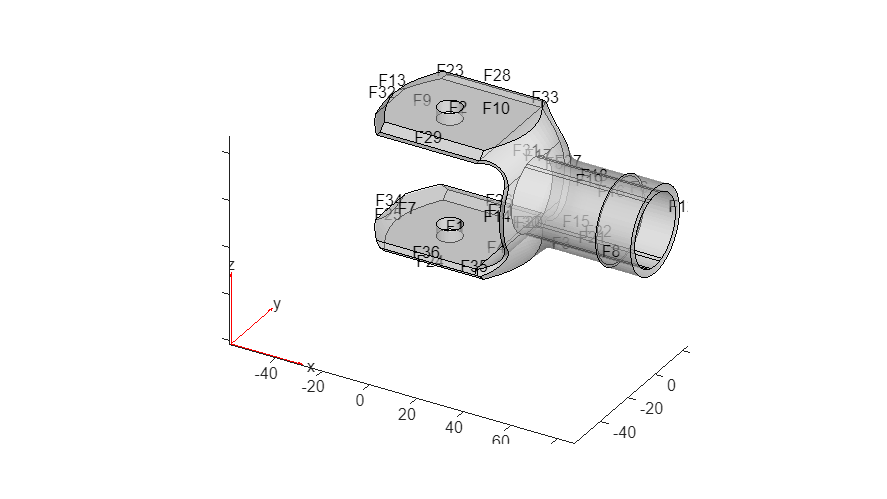

figure('Units','normalized', 'Position',[0 0 0.4 0.4])
pdegplot(feModel,'FaceLabels','on','FaceAlpha',0.5)
axis equal

faceIDs = [2, 8,1];    % Required Input

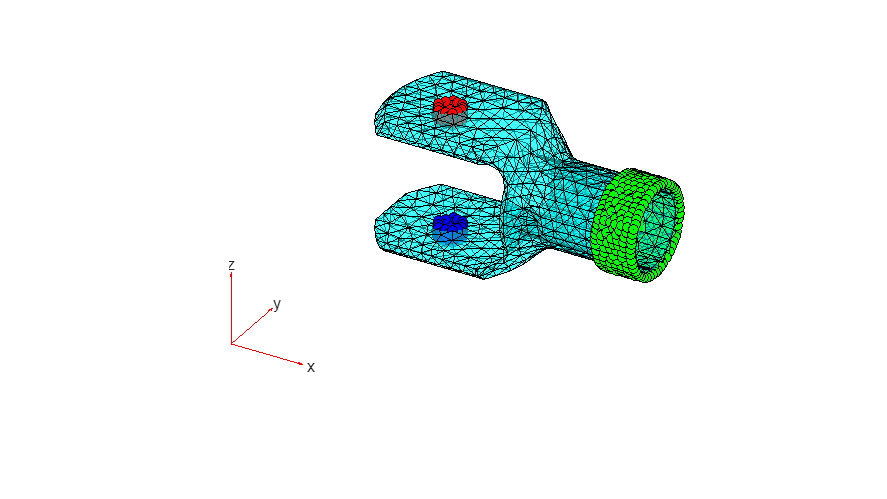

figure('Units','normalized', 'Position',[0 0 0.4 0.4])
pdemesh(feModel,'FaceAlpha',0.5)
hold on
colors = ['rgb' repmat('k',1,numFrames-3)];
assert(numel(faceIDs) == numFrames);
for k = 1:numFrames
    nodeIdxs = findNodes(feModel.Mesh,'region','Face',faceIDs(k));
    scatter3( ...
        feModel.Mesh.Nodes(1,nodeIdxs), ...
        feModel.Mesh.Nodes(2,nodeIdxs), ...
        feModel.Mesh.Nodes(3,nodeIdxs), ...
        'ok','MarkerFaceColor',colors(k))
    scatter3( ...
        origins(k,1), ...
        origins(k,2), ...
        origins(k,3), ...
        80,colors(k),'filled','s')
end
hold off

for k = 1:numFrames
    structuralBC(feModel, ...
        'Face',faceIDs(k), ...
        'Constraint','multipoint', ...
        'Reference',origins(k,:));
end

## Step 5 - Generate the Reduced-Order Model

rom = reduce(feModel,'FrequencyRange',[0 1e4]);

gimbals.P = rom.ReferenceLocations';  % Interface frame locations (n x 3 matrix)
gimbals.K = rom.K;                    % Reduced stiffness matrix
gimbals.M = rom.M;

dampingRatio = 0.01;
gimbals.C = computeModalDampingMatrix(dampingRatio,rom.K,rom.M);

frmPerm = zeros(numFrames,1);    % Frame permutation vector
dofPerm = 1:size(gimbals.K,1);       % DOF permutation vector

assert(size(gimbals.P,1) == numFrames);
for i = 1:numFrames
    for j = 1:numFrames
        if isequal(gimbals.P(j,:),origins(i,:))
            frmPerm(i) = j;
            dofPerm(6*(i-1)+(1:6)) = 6*(j-1)+(1:6);
            continue;
        end
    end
end
assert(numel(frmPerm) == numFrames);
assert(numel(dofPerm) == size(gimbals.K,1));

gimbals.P = gimbals.P(frmPerm,:);
gimbals.K = gimbals.K(dofPerm,:);
gimbals.K = gimbals.K(:,dofPerm);
gimbals.M = gimbals.M(dofPerm,:);
gimbals.M = gimbals.M(:,dofPerm);
gimbals.C = gimbals.C(dofPerm,:);
gimbals.C = gimbals.C(:,dofPerm);

gimbals.numFrames = numFrames;

## Step 6 - Import reduced-Order Data

**Interface Frames - Number of Frames --> gimbals.numFrames**

**Interface Frames - Origins --> gimbals.P**

**Reduced Order matrices - Stiffness Matrix --> gimbals.K(1:24, 1:24)**

**Reduced Order matrices - Mass Matrix --> gimbals.M(1:24, 1:24)**

**Damping - Damping matrix --> gimbals.C(1:24,1:24)**

[~, fileName, ~] = fileparts(gimbalsModel);
save([fileName, '.mat'], 'gimbals');

function C = computeModalDampingMatrix(dampingRatio,K,M)

% To avoid numerical issues (such as complex eigenvalues with very small
% imaginary parts), make the matrices exactly symmetric.

    K = (K+K')/2;    % Stiffness matrix
    M = (M+M')/2;    % Mass matrix

% Compute the eigen-decomposition associated with the mass and stiffness
% matrices, sorting the eigenvalues in ascending order and permuting
% the corresponding eigenvectors.

    [V,D] = eig(K,M);
    [d,sortIdxs] = sort(diag(D));
    V = V(:,sortIdxs);

% Due to small numerical errors, the six eigenvalues associated with the
% rigid-body modes may not be exactly zero. To avoid numerical issues,
% check that the first six eigenvalues are close enough to zero. Then
% replace them with exact 0 values.

    assert(all(abs(d(1:6))/abs(d(7)) < 1e-9),'Error due to "zero" eigenvalues.');
    d(1:6) = 0;

% Vectors of generalized masses and natural frequencies

    MV = M*V;
    generalizedMasses = diag(V'*MV);
    naturalFrequencies = sqrt(d);

% Compute the modal damping matrix associated with K and M

    C = MV * diag(2*dampingRatio*naturalFrequencies./generalizedMasses) * MV';

end